%clearing
clear;
clc;
close all;

%excel file import
filename = 'fulldata.xlsx';
cdata = readmatrix(filename);
disp(size(cdata));

   120    10




cdata1 = cdata(:,:);

returns = diff(cdata1) ./ cdata1(1:end-1, :);

range0 = returns(1:59,:);
range1 = returns(60:72,:);
n = 12;
Sigma0 = cov(range0);
Sigma1 = cov(range1);

mu0 = mean(range0)';
mu1 = mean(range1)';

% Calculate the inverse of Sigma0 and Sigma1
Sigma0_inv = inv(Sigma0);
Sigma1_inv = inv(Sigma1);

% Calculate the inverse of (Sigma0_inv + n*Sigma1_inv)
Sigma_star_inv = Sigma0_inv + n * Sigma1_inv;
Sigma_star = inv(Sigma_star_inv);

% Calculate mu_star
mu_star = Sigma_star * (Sigma0_inv * mu0 + n * Sigma1_inv * mu1);

% Display the results
disp('mu_star:');

mu_star:


disp(mu_star);

    0.0058
    0.0107
   -0.0067
    0.0483
    0.0081
    0.0190
   -0.0067
   -0.0026
   -0.0271
   -0.0161



disp('Sigma_star:');

Sigma_star:


disp(Sigma_star);

   1.0e-03 *

    0.1679    0.0482    0.0622    0.1579    0.1420    0.0920    0.0807    0.1167    0.0931    0.1478
    0.0482    0.6014    0.1225    0.3339    0.2262    0.1829    0.1793    0.2772    0.2950    0.3301
    0.0622    0.1225    0.3010    0.2645    0.1389    0.0752    0.1153    0.1800    0.1909    0.1912
    0.1579    0.3339    0.2645    0.7725    0.3200    0.1314    0.2040    0.1938    0.3117    0.3558
    0.1420    0.2262    0.1389    0.3200    0.2267    0.1207    0.1444    0.1898    0.2110    0.2551
    0.0920    0.1829    0.0752    0.1314    0.1207    0.1490    0.0738    0.1407    0.0614    0.0966
    0.0807    0.1793    0.1153    0.2040    0.1444    0.0738    0.1429    0.1586    0.2456    0.2596
    0.1167    0.2772    0.1800    0.1938    0.1898    0.1407    0.1586    0.3002    0.2475    0.2906
    0.0931    0.2950    0.1909    0.3117    0.2110    0.0614    0.2456    0.2475    0.4846    0.4801
    0.1478    0.3301    0.1912    0.3558    0.2551    0.0966    0.2596    0.2



%PCA section

% doing pca
[coeff, latent, explained] = pcacov(Sigma_star);

%
explained_variance = cumsum(explained);
num_components = find(explained_variance >= 100, 1); %we can change this, varying this allows us to experiment and decide what we can change here, how it affects computation time
disp(num_components);

    10




%dimensionality reduction
coeff_reduced = coeff(:, 1:num_components);
latent_reduced = latent(1:num_components); %check this

% mean is smaller subsace, variance too
%have to project via transpose of the new coeffs
%mean_reduced = coeff_reduced' * in_sample_mean;
cov_reduced = diag(latent_reduced);
%cov_reduced = coeff_reduced' * latent_reduced * coeff_reduced;

% bring back to original space

%to create pxn matrix, multiple x (diagonal)  x(^t)
in_sample_cov_reconstructed = coeff_reduced * cov_reduced * coeff_reduced';

num_assets = size(mu_star, 1);

% rf rate for sharpe calculation
rf = 0.00;
shortselltoggle = 0;
% we aim to find the lowest risk possible for each interval between
% returns. Accuracy increases with the more number of portfolios.
target_returns = linspace(min(mu_star), max(mu_star), 100);

% Array setup
portfolio_risks = zeros(length(target_returns), 1);
portfolio_returns = zeros(length(target_returns), 1);
portfolio_weights = zeros(length(target_returns), num_assets);

% Solve the optimization problem for each linspaced return
options = optimoptions('quadprog', 'Display', 'off');
for i = 1:length(target_returns)
    target_return = target_returns(i);
    
    % Define the optimization problem
    f = zeros(num_assets, 1); %no constant
    Aeq = ones(1, num_assets); %sum(weights) ==1, we can change this to -1 to 1 to allow for shortselling
    beq = 1;
    A = -mu_star'; % mean return >= target return
    b = -target_return;
    if (shortselltoggle == 0    )
        lb = zeros(num_assets, 1);
        ub = ones(num_assets, 1);
    else
        lb = -1 *ones(num_assets, 1);
        ub = ones(num_assets, 1);
    end

    % Solve the quadratic programming problem
    [x, ~, solutionindicator] = quadprog(in_sample_cov_reconstructed, f, A, b, Aeq, beq, lb, ub, [], options);
    
    if solutionindicator == 1 % Solution found
        portfolio_weights(i, :) = x';
        portfolio_returns(i) = mu_star' * x;
        portfolio_risks(i) = sqrt(x' * in_sample_cov_reconstructed * x);
    else
        portfolio_weights(i, :) = NaN;
        portfolio_returns(i) = NaN;
        portfolio_risks(i) = NaN;
    end
end

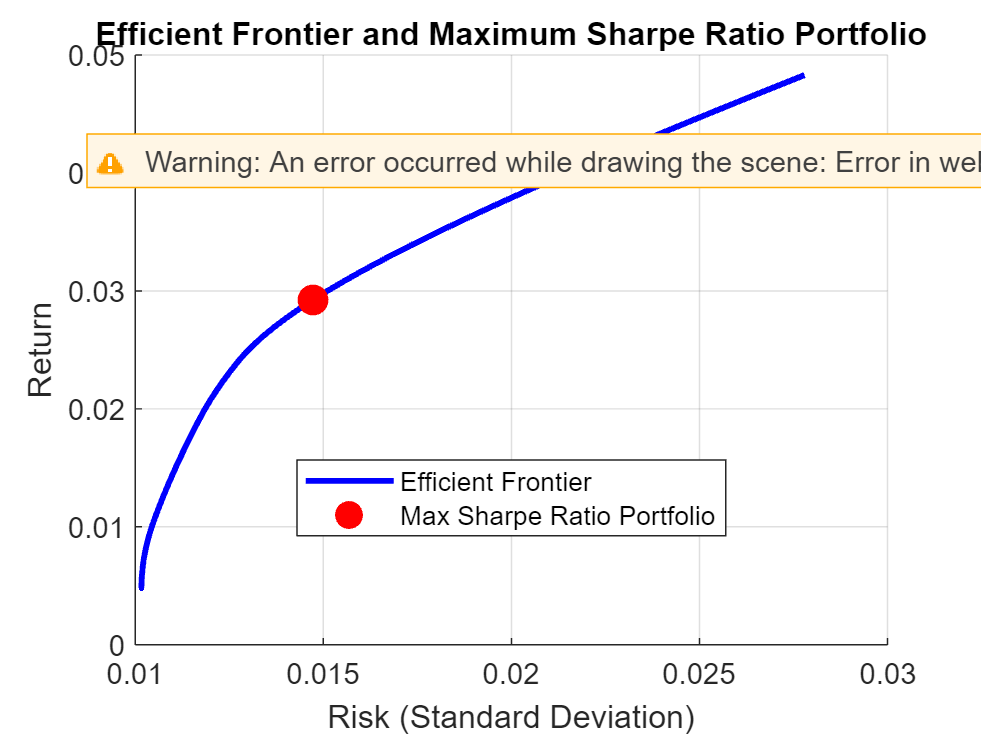


% Remove NaN values
valid_indices = ~isnan(portfolio_returns);
portfolio_risks = portfolio_risks(valid_indices);
portfolio_returns = portfolio_returns(valid_indices);
portfolio_weights = portfolio_weights(valid_indices, :);

%find the sharpe ratios for each generated portfolio
sharpe_ratios = (portfolio_returns - rf) ./ portfolio_risks;

%locate portfolio with max sharpe ratio
[~, sharpehigh] = max(sharpe_ratios);
%return parameters
max_sharpe_weights = portfolio_weights(sharpehigh, :);
max_sharpe_return = portfolio_returns(sharpehigh);
max_sharpe_risk = portfolio_risks(sharpehigh);



%Efficient Frontier plot with risk free rate line (CML)
figure;
hold on;
plot(portfolio_risks, portfolio_returns, 'b-', 'LineWidth', 2);

plot(max_sharpe_risk, max_sharpe_return, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
xlabel('Risk (Standard Deviation)');
ylabel('Return');
title('Efficient Frontier and Maximum Sharpe Ratio Portfolio');
legend('Efficient Frontier', 'Max Sharpe Ratio Portfolio', 'Location', 'Best');
grid on;


%
disp('weights for the high sharpe ratio portfolio');

weights for the high sharpe ratio portfolio


disp(max_sharpe_weights);

    0.0000    0.0000    0.0000    0.3490    0.0000    0.6510    0.0000    0.0000    0.0000    0.0000




disp(['Maximum Sharpe Ratio: ', num2str(sharpe_ratios(sharpehigh))]);

Maximum Sharpe Ratio: 1.9856


disp(['Expected Portfolio Return: ', num2str(max_sharpe_return)]);

Expected Portfolio Return: 0.029248


disp(['Portfolio Risk (Standard Deviation): ', num2str(max_sharpe_risk)]);

Portfolio Risk (Standard Deviation): 0.01473
